# Monk skin tone analysis

for Josh and Sandhya's melanometry project

WCC, 12/14/2022

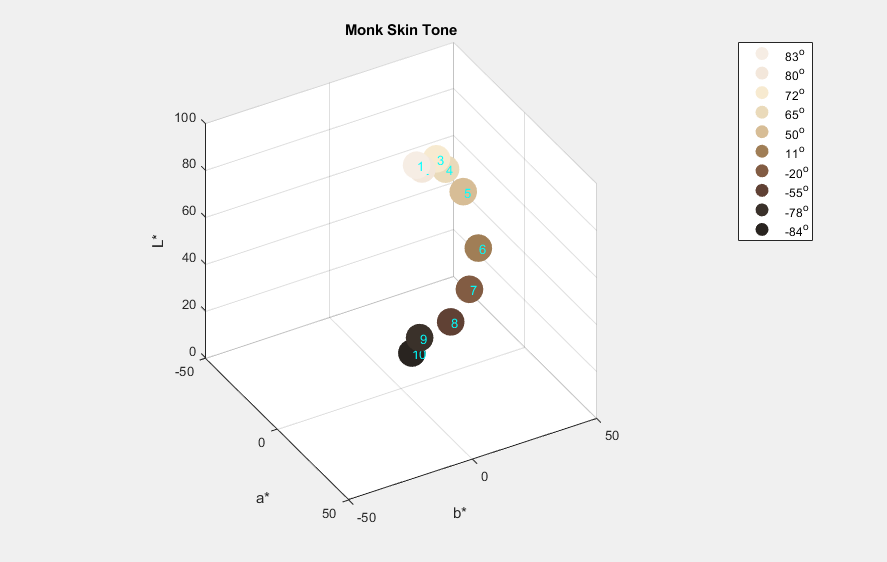

mst = MonkSkinTone;
fst = FitzPatrickSkinTone;

clf; show_3D_view(mst); title('Monk Skin Tone'); create_animation('mst_3D.gif')

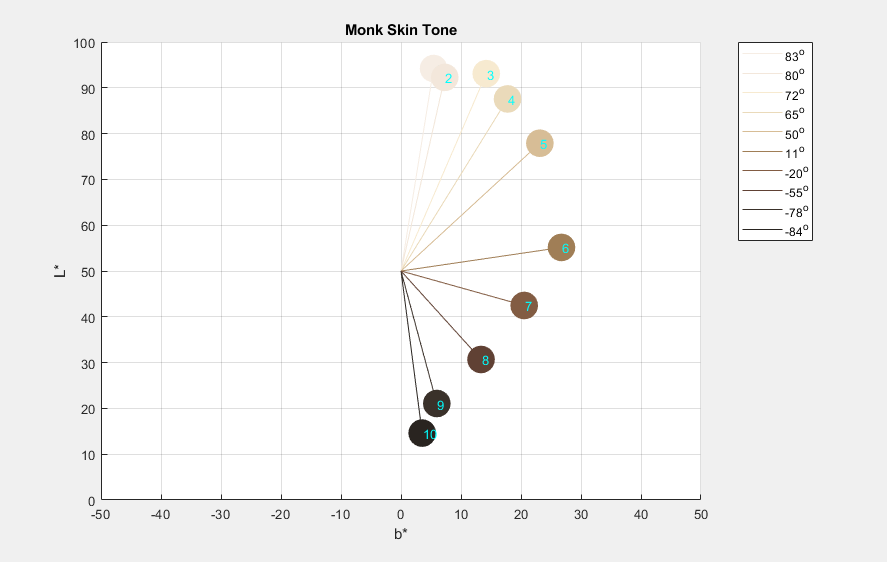

clf; show_ita_on_Lb(mst); title('Monk Skin Tone'); saveas(gca,'mst_Lb.png')

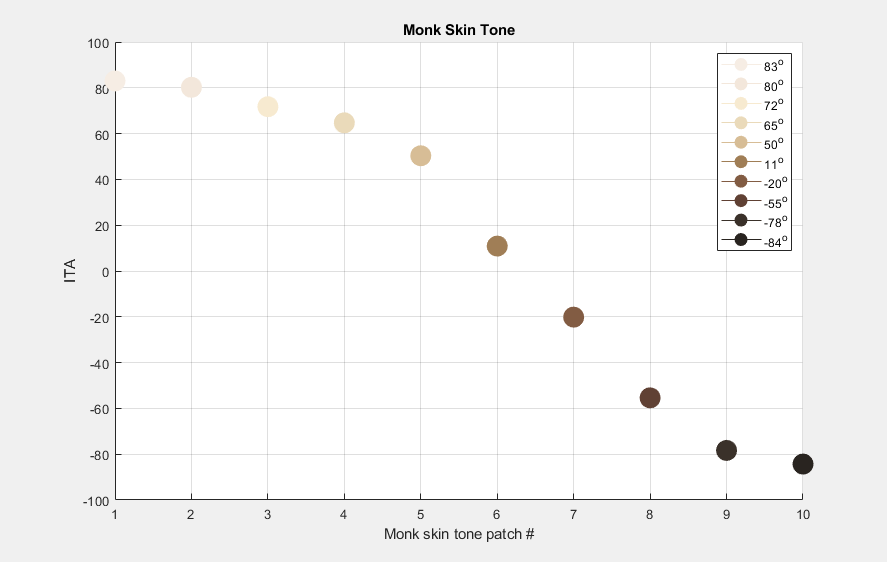

clf; show_ita_trend(mst); title('Monk Skin Tone'); saveas(gca,'mst_trend.png')

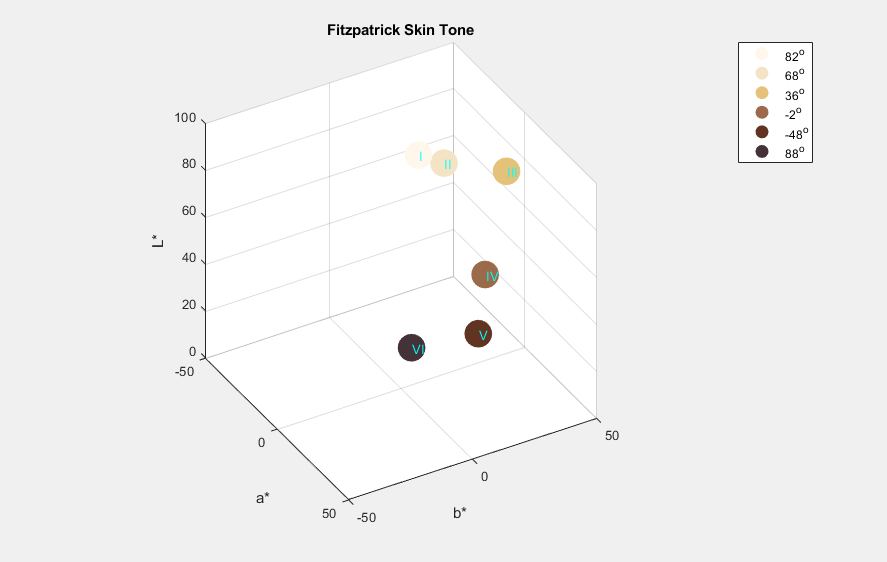


clf; show_3D_view(fst); title('Fitzpatrick Skin Tone'); create_animation('fst_3D.gif')

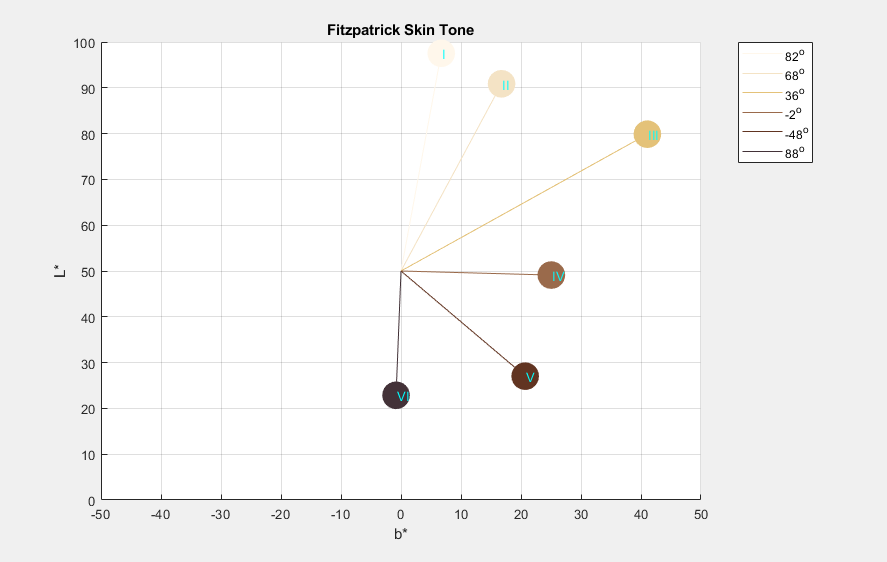

clf; show_ita_on_Lb(fst); title('Fitzpatrick Skin Tone'); saveas(gca,'fst_Lb.png')

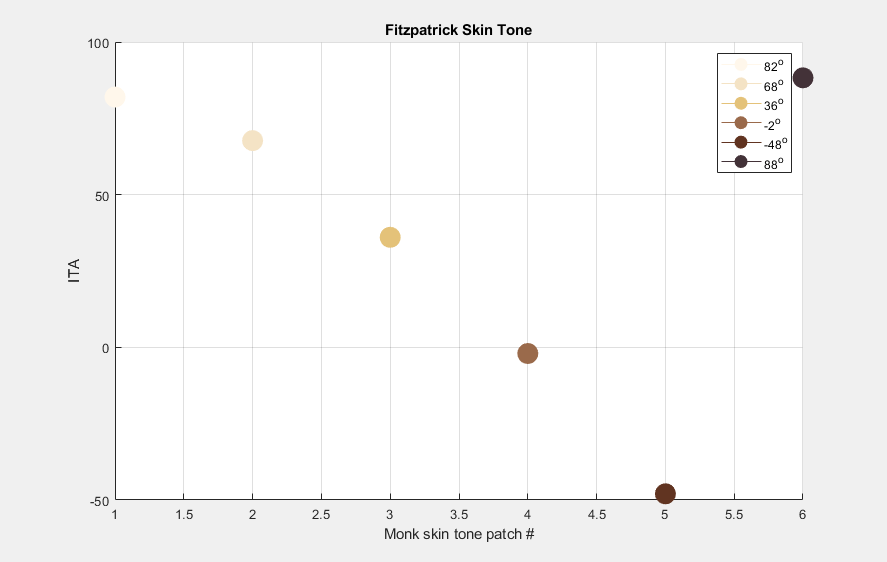

clf; show_ita_trend(fst); title('Fitzpatrick Skin Tone'); saveas(gca,'fst_trend.png')


return

## Show 3D view

function show_3D_view (st)

marker_dist = 0.1;
lab = st.lab;

clf
hg = gcf;
set(gcf,'Visible','on')
hold on


center = [0 0 50];

for i=1:st.n
    plot3(lab(i,2),lab(i,3),lab(i,1),'o','MarkerSize',20,'MarkerFaceColor',st.rgb(i,:)/255,'MarkerEdgeColor',st.rgb(i,:)/255)
    text(lab(i,2)+marker_dist,lab(i,3)+marker_dist,lab(i,1),st.marker{i}, ...
        'Color','c')

    lgn{i} = sprintf('%.0f^o',st.ita(i));
end

axis([-50 50 -50 50 0 100])
xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view(60,35)
legend(lgn)

end

## Show ITA on CIE L*b*

function show_ita_on_Lb (st)
marker_dist = 0.1;
lab = st.lab;

clf
hg = gcf;
set(gcf,'Visible','on')
hold on


center = [0 0 50];

for i=1:st.n
    plot3(lab(i,2),lab(i,3),lab(i,1),'o','MarkerSize',20,'MarkerFaceColor',st.rgb(i,:)/255,'MarkerEdgeColor',st.rgb(i,:)/255)
    text(lab(i,2)+marker_dist,lab(i,3)+marker_dist,lab(i,1),st.marker{i}, ...
        'Color','c')

    lgn{(i-1)*2+1} = '';
    lgn{(i-1)*2+2} = sprintf('%.0f^o',st.ita(i));

    p_from = center;
    p_to = [st.lab(i,2) st.lab(i,3) st.lab(i,1)];
    p_from_to = [p_from; p_to];
    plot3(p_from_to(:,1),p_from_to(:,2),p_from_to(:,3),'-','Color',st.rgb(i,:)/255)
    
end

axis([-50 50 -50 50 0 100])
xlabel('a*')
ylabel('b*')
zlabel('L*')
grid on
view([1 0 0])
legend(lgn)
end

## Show ITA trend

function show_ita_trend (st)

clf
hold on
lgn = {};
for i = 1:st.n
    plot(i,st.ita(i),'o-', ...
        'MarkerFaceColor',st.rgb(i,:)/255, ...
        'MarkerEdgeColor',st.rgb(i,:)/255, ...
        'Color',st.rgb(i,:)/255, ...
        'MarkerSize',15)
    lgn{i} = sprintf('%.0f^o',st.ita(i));
end
grid on
legend(lgn)
xlabel('Monk skin tone patch #')
ylabel('ITA')
end